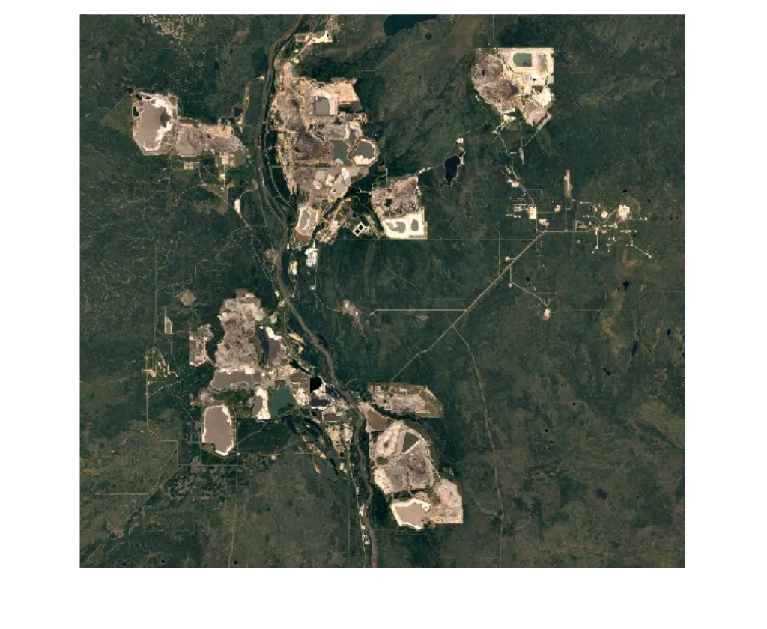

clear
img = imread('images/alberta/mining_2022.png');
imshow(img)


img = imresize(img, 0.25); % for computational efficiency 

img = im2double(img);
r = img(:,:,1);
r = reshape(r.',1,[]);
g = img(:,:,2);
g = reshape(g.',1,[]);
b = img(:,:,3);
b = reshape(b.',1,[]);

hsv = rgb2hsv(img);
h = hsv(:,:,1);
h = reshape(h.',1,[]);
s = hsv(:,:,2);
s = reshape(s.',1,[]);
v = hsv(:,:,3);
v = reshape(v.',1,[]);

length(img)

ans = 203

length(img(:,1))

ans = 185


x = 1:length(img);
x = repmat(x, length(img(:,1)), 1);
x = reshape(x.',1,[]);
y = transpose(1:length(img(:,1)));
y = repmat(y, 1, length(img));
y = reshape(y.',1,[]);

r_scale = r/max(r);
g_scale = g/max(g);
b_scale = b/max(b);

h_scale = h(1:1:end)/max(h);
s_scale = s(1:1:end)/max(s);
v_scale = v(1:1:end)/max(v);

x_scale = x(1:1:end)/max(x);
y_scale = y(1:1:end)/max(y);

data = [2*h_scale; s_scale; 2*v_scale; x_scale; y_scale]';

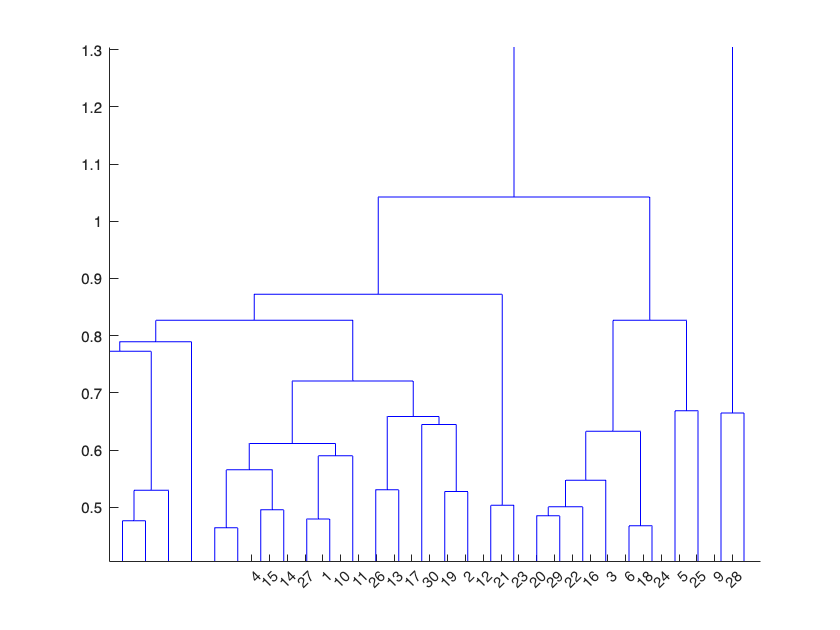

Z = linkage(data,'average');
figure
dendrogram(Z)

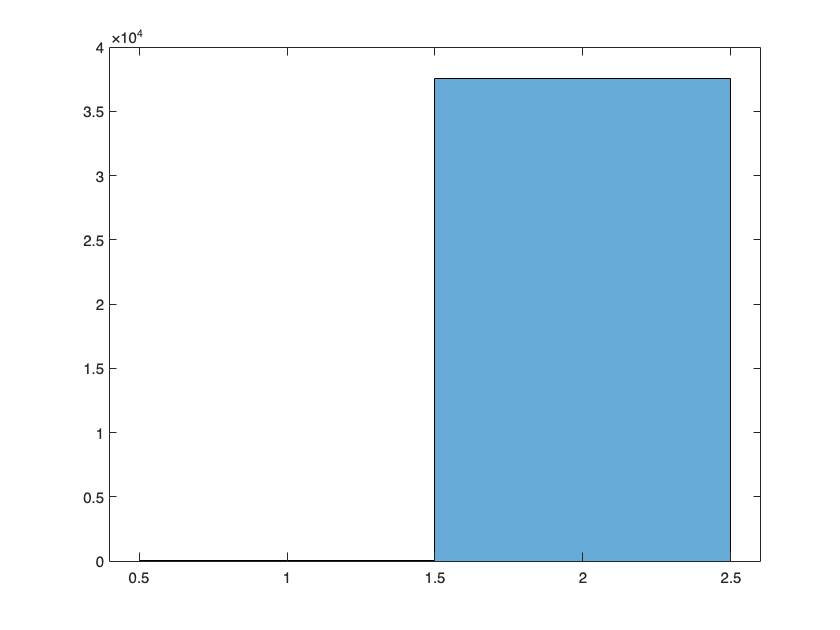

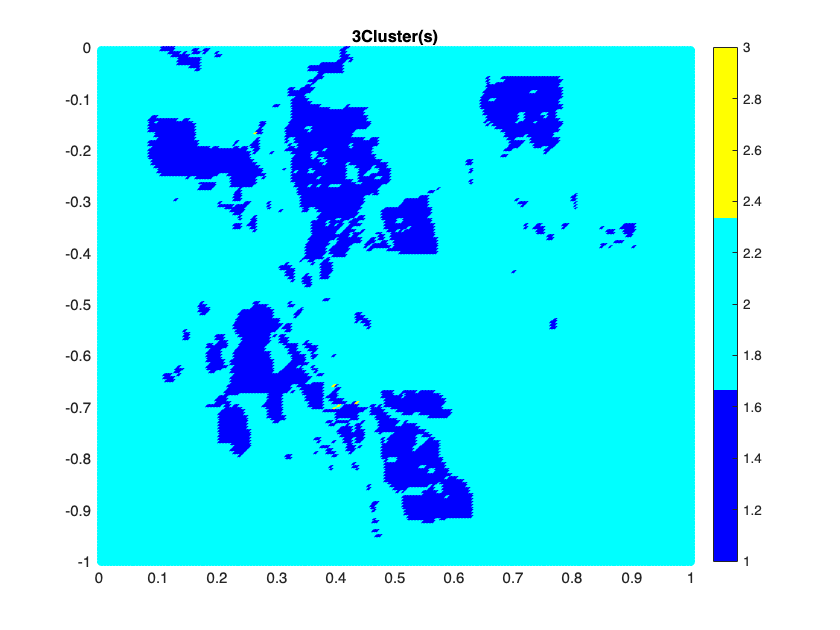

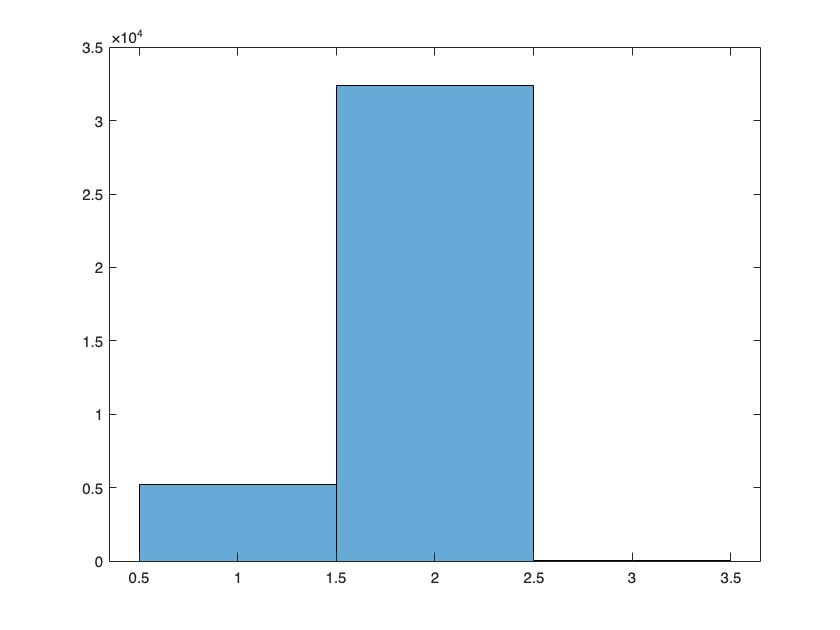

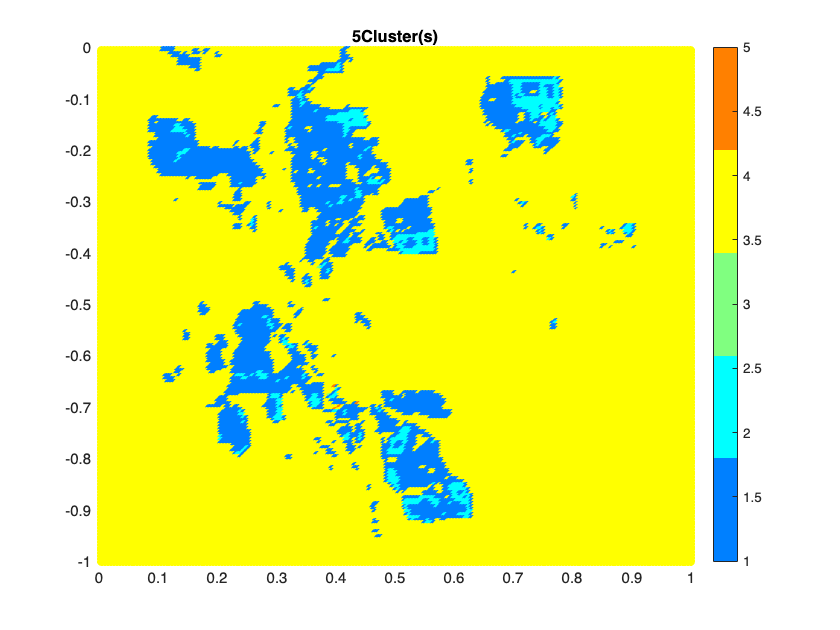

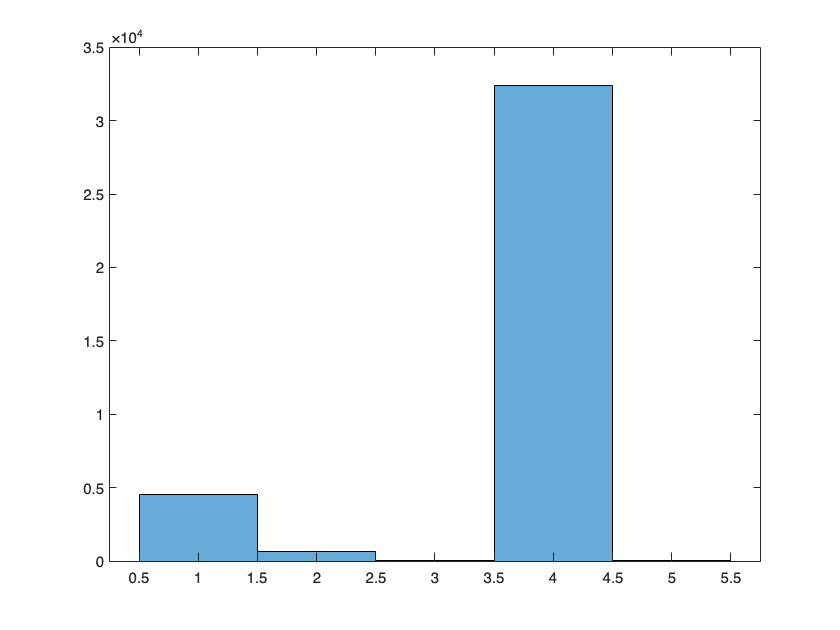

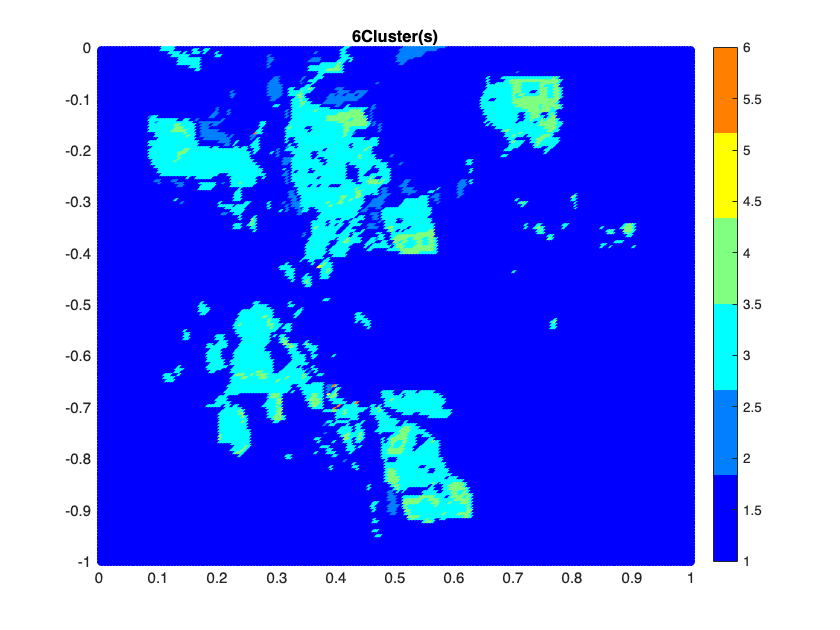

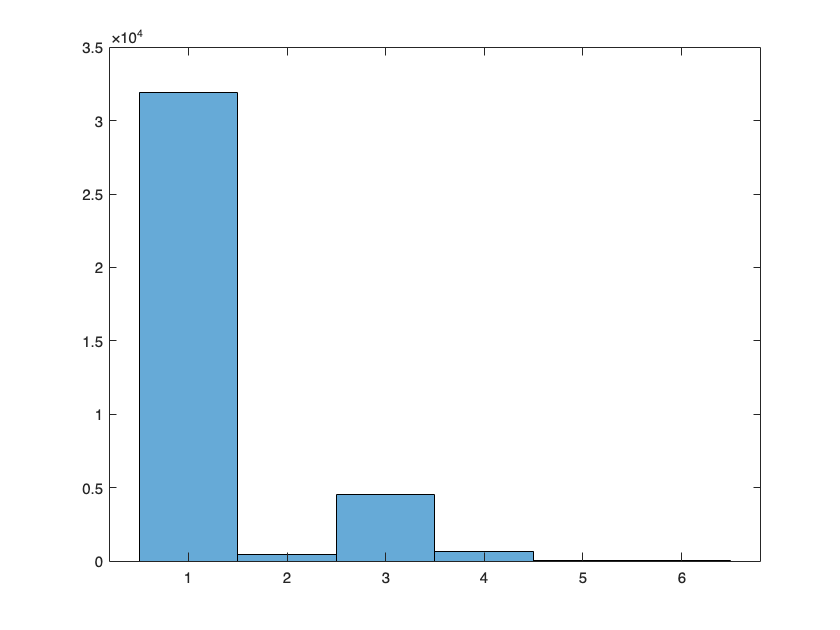

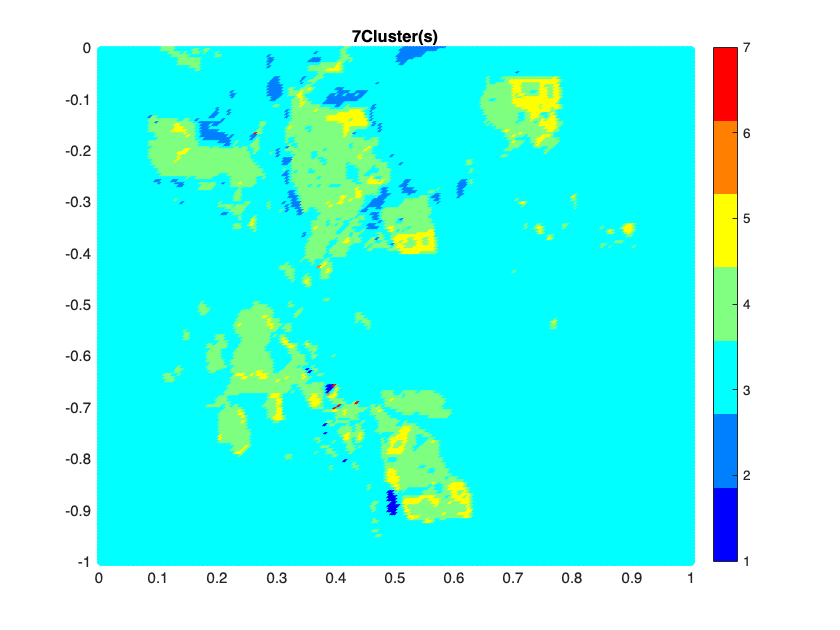


max = [];
for num = [2,3,5,6,7,8,9,10]
    c = cluster(Z,'Maxclust', num);

    figure
    scatter(x_scale, -y_scale, [], c, 'filled')
    colormap(jet(length(unique(c))));
    colorbar
    title(string(num)+"Cluster(s)")
    
    figure
    histogram(c)

end

%Todo: Elbow method

